% Robust fit of a multiple parametric model instances to data
% Mathematical Models and Methods, 2022
% Giacomo Boracchi, 
% Politecnico di Milano
% giacomo.boracchi@polimi.it 
% 
%
% Credits Luca Magri, Politecnico di Milano

addpath(genpath('.'))
clc;
clear;
close all;

%% load data
%temp = load('data/star5');
%temp = load('data/stair4');
temp = load('data/circle5');

X = temp.X; % data
G = temp.G; % ground truth or label (>1: normal, 0: outlier)
clear temp;

%% model specification
% functions to fit and compute residuals are already invoked in the function

%set this to 3 when running on circles
%set it to 2 when running on lines
cardmss = 3; % minimum number of points required to fit a model
kappa = max(G); % number of models to be extracted by sequential ransac
%% plotting params
bw = 0.01;
col = 'b';
temp = load('cmap.mat');
cmap = temp.cmap; clear temp;

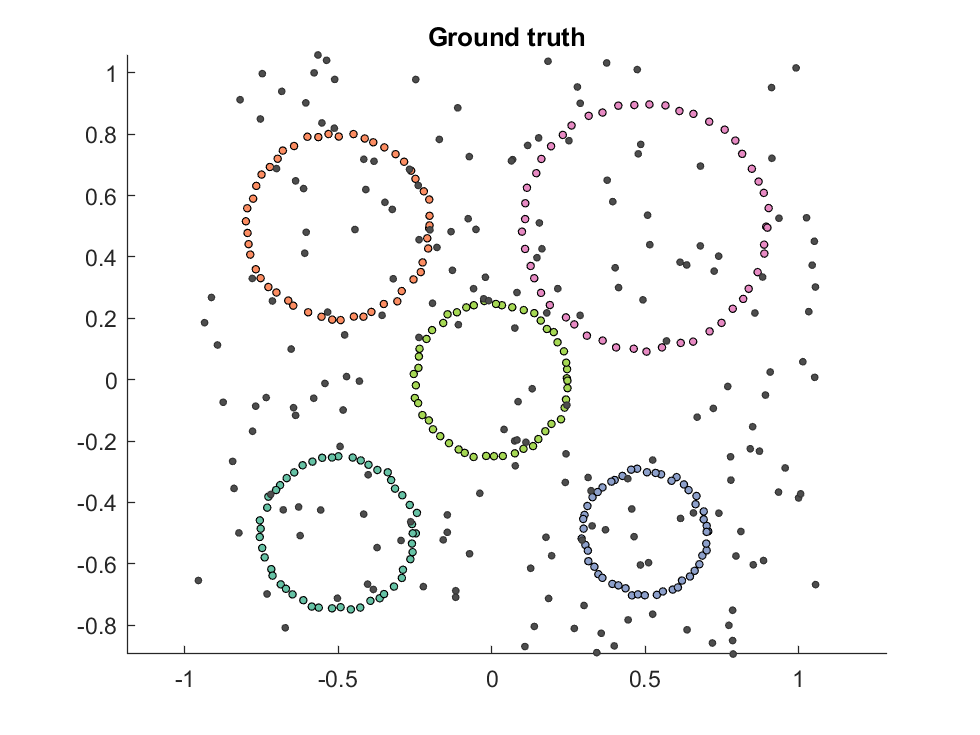

%% Prepare dataset

% add outliers
nOut = 200;

% add outlier and update groundtruth
X = addOutliersInBB(X,nOut);

% update the label, considering that X previous command has appended nOut otliers 
G = [G;zeros(nOut, 1)];

% visualization
figure(1);
display_clust(X,G, cmap);
title('Ground truth');
axis equal

%% sequential ransac
epsi = 0.02; % inlier threshold for ransac
Y = X; % take a copy of X to be modified

% define cells to contain the fitted models
currentModel = cell(1,kappa);
currentInliers = cell(1,kappa);
iter = 1;

do_debugPlot =0;
know_kappa = 0;
% = 1 runs the algorithm for kappa iterations, otherwise runs until
% consensus decreases too much



% implement sequential ransac by a loop, 
% stop when the consensus becomes smaller than the threshold
% This way we dont have to know the number of elements a priori
cons = Inf;
minconsensus = 0;
flag = true;

if know_kappa
    disp(['Assuming to know the number of models to be extracted'])
    while iter <= kappa
        disp(['Running Iteration', num2str(iter)])
        % find model with ransac (save currentModel and currentInliers for visualization)
        [bestmodel, bestinliers] = simpleRANSAC(Y, cardmss, epsi, do_debugPlot);        
        if cardmss == 2
            refined_model = fit_line_dlt(Y(:,bestinliers));
        else
            refined_model = bestmodel;
        end
        % remove current inliers
        Y = Y(:, ~ bestinliers);
        currentModel{iter} = refined_model;
        currentInliers{iter} = find(bestinliers);   
        iter = iter +1;
    end
    iter = iter-1;
else
    while flag
        disp(["Running Iteration", num2str(iter)])
        % find model with ransac (save currentModel and currentInliers for visualization)
        [bestmodel, bestinliers] = simpleRANSAC(Y, cardmss, epsi, do_debugPlot);

        % update consensus
        cons = max(size(find(bestinliers),1),size(find(bestinliers),2));
        
        %The minimum consensus is 90% of the average of the previous iterations
        %consensus
        minconsensus = 0.9*( cons/iter + minconsensus*(iter-1)/iter);
        if cons > minconsensus
            if cardmss == 2
                refined_model = fit_line_dlt(Y(:,bestinliers));
            else
                %OLS for circles seems better because my implementation of
                %DLT heavily depends on the estimation of the center of the
                %circle, that is set as the barycentre of the inliers...
                
                refined_model = fit_circle_ols(Y(:,bestinliers));
                %refined_model = fit_circle_dlt(Y(:,bestinliers));
            end
            % remove current inliers
            Y = Y(:, ~ bestinliers);
            currentModel{iter} = refined_model;
            currentInliers{iter} = find(bestinliers);
        else
            flag = false;
            disp(['During iteration ', num2str(iter), ' Ransac reached consensus ', num2str(cons), ' that is under the minimum consensus ', num2str(minconsensus)])
        end
        iter = iter +1;
    end
    iter = iter-2;
    disp(['Estimated number of models: ', num2str(iter)])
end

    "Running Iteration"    "1"



Ransac Iterations: 2387


    "Running Iteration"    "2"



Ransac Iterations: 1889


    "Running Iteration"    "3"



Ransac Iterations: 1157


    "Running Iteration"    "4"



Ransac Iterations: 771


    "Running Iteration"    "5"



Ransac Iterations: 422


    "Running Iteration"    "6"



Ransac Iterations: 4112


During iteration 6 Ransac reached consensus 19 that is under the minimum consensus 32.269


Estimated number of models: 5


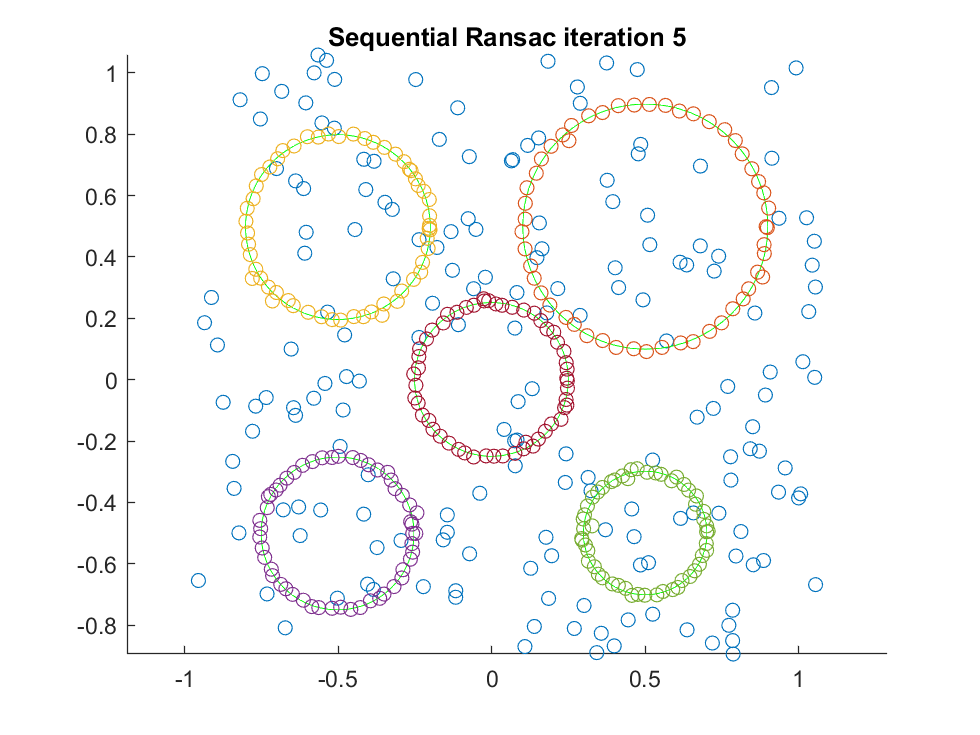


%% shows Sequential Ransac Iterations
figure(3), cla
hold on
axis equal
Y = X;
scatter(X(1,:),X(2,:));

for i = 1:iter %kappa
    % display a band for each model estimated (see display_band function)
    if cardmss == 2
        display_band(Y(:, currentInliers{i}), currentModel{i}, epsi, col)
    else
        theta = currentModel{i};
        center = [theta(1)/2;theta(2)/2];
        radius = sqrt(theta(1)^2/4 + theta(2)^2/4 + theta(3));
        plot_circle(center(1), center(2), radius, 'g')
    end

    % plot inliers for this model
    scatter(Y(1,currentInliers{i}),Y(2,currentInliers{i}));

    % you need to remove the inliers you have plot from Y, otherwise the indexes are wrong
    Y(:, currentInliers{i}) = [];
    title(sprintf('Sequential Ransac iteration %i',i))
    pause(0.5)
end
hold off;